# **Model-Based Unit Testing**

The purpose of this work is to develop a model-based unit testing method in MOBATSim, which combines requirement-based testing and scenario-based testing to test model components to verify that the tested model components meet all design requirements, and the tests performed on the components are sufficient.

Based on requirement-based testing, it is necessary to first define the functional requirements of the tested model component as a standard that the model components must meet, and then isolate each tested component from the main model by creating a Test Harness Model for the tested component. By writing requirement-based assessments, the requirements are changed from a language that the machine cannot understand to a test evaluation standard that can be understood and used by the machine in the test. Based on scenario-based testing to create test inputs for the test of the component under test, each test input vector represents a specific test scenario. Use the tool Simulink Test Manager to create and manage test cases, and run test cases to execute tests. Requirement-based assessments are used to assess whether the test cases meet the requirements, and the tool Simulink Coverage is used to analyze whether the executed tests are complete.

# **Table of Contents**

# **Ⅰ. Determine Model Components under Test**

First determine the model components that need to be tested. Some specific blocks need to be modified or replaced before building the test.

## A. Individual Blocks

Individual blocks are single model components, which does not contain other simulink blocks.

### 1. MATLAB System Blocks

System objects let you implement algorithms using the MATLAB language. The [MATLAB System](https://www.mathworks.com/help/simulink/slref/matlabsystem.html) block enables you to use System objects in Simulink.

In our test method, we need to use the tool Simulink Coverage to evaluate the test completeness in the test of model components, and for MALTAB System blocks, Simulink Coverage cannot perform model analysis for MATLAB System block with **Simulate using** parameter set to **Interpreted execution**. In our model, that happens to be the case:

Therefore, in order to be able to use Simulink Coverage to evaluate the test coverage of all tested components, it is necessary to convert the tested MATLAB System blocks into other types of blocks and then perform the test. Here, we choose to convert MATLAB System blocks into Stateflow Charts.

To go back to Table of Contents

### 2. Simulink Blocks

These blocks are single simulink blocks in the Block Libraries.

## B. Composed Blocks

In our model, such composed blocks are the subsystem blocks that contain some simulink blocks in the Block Libraries.

# **Ⅱ. Define Functional Requirements**

The purpose of testing here is to verify that the designed model or model components meet our design requirements or industry standards. To this end, you must first define functional requirements for the test of the model, and specify which requirements each model component under test needs to satisfy. The requirements of each tested model component are regarded as the design specifications of the component.

The tool **Simulink Requirements** lets you author, analyze, and manage requirements within Simulink. With Simulink Requirements, you can create requirements with custom attributes and link them to model components, code, and tests. You can also analyze requirements traceability, and navigate between requirements, model components, generated code, and tests.

For more detailed information about Simulink Requirements, please click [here](https://www.mathworks.com/help/slrequirements/index.html?s_tid=CRUX_lftnav).

To go back to Table of Contents

## **A. Analyze Model/Block Structure**

Analyze the structure of the tested block to determine the role of the block and all the functions implemented by the block. All restrictions and all functions of the tested block are used to define functional requirements.

To go back to Table of Contents

## **B. Create Requirements**

A requirement is a text format described in natural language and does not contain logic that can be understood by machines. A requirement specifies a function/condition that the corresponding block needs to satisfy. You can add detailed text, images, and keywords to describe a requirement. 

You can create a new requirement set and its requirements in the Requirements Editor or Requirements Browser.

To go back to Table of Contents

### 1. Requirements Editor

The Requirements Editor can be used to create and manage all requirement sets and their requirements.

On the main model interface, click **APPS** in the upper menu bar, then click **Requirements Manager** in the options below.  In the **Requirements** tab, click **Requirements Editor** to open the editor.

You can also use the following code to directly open the Requirements Editor:

slreq.editor     %Open Requirements Editor

You can directly run the following code to open an existing requirements set:

slreq.open('export_Requirements_MOBATSim')     %Open existing requirements set
% slreq.open('RequirementsSet_name')

From the Requirements Editor toolbar, click **New Requirement Set **to create a new requirement set:

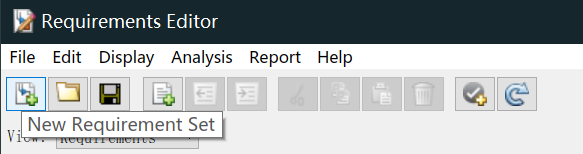

You can also use the following code to create a new requirement set:

newReqSet1 = slreq.new(reqSetName)  %creates a requirement set named reqSetName in the current working folder

newReqSet2 = slreq.new(reqSetPath)  %creates a requirement set on the specified path

You can select all the options in the **Display** in the menu bar to view different information, especially the options "Implementation Status" and "Verification Status":

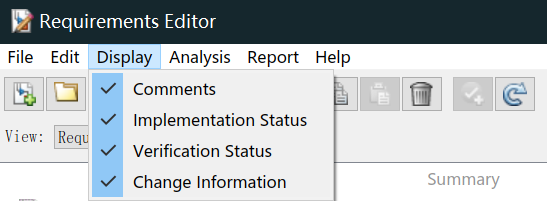

"Implementation Status" shows whether this requirement is linked to the block that implements it.

"Verification Status" shows whether this requirement is linked to the test case used to verify it.

Right click on the newly created requirement set to add a new requirement, and then click on the newly created requirement, you can author your requirements by writing the content, ID, summary etc. in the** Properities** tab displayed on the right:

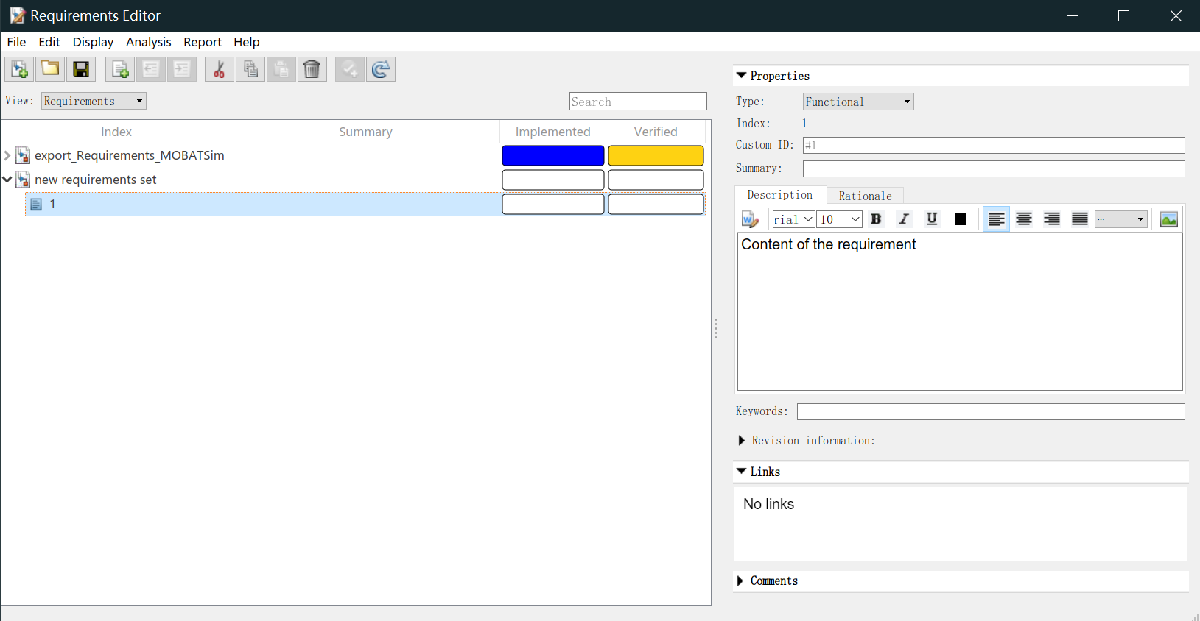

To go back to Table of Contents

### 2. Requirements Browser

The Requirements Browser is similar to the aforementioned Requirements Editor. Both are used to create and manage requirement sets and their requirements. The requirements created in these two tools are compatible with each other and can be opened directly in another tool.

In the slimulink model interface, click the icon** Show Perspectives views** in the lower right corner, and then click **Enter Perspective Requirements** to enter the Requirements Perspective.

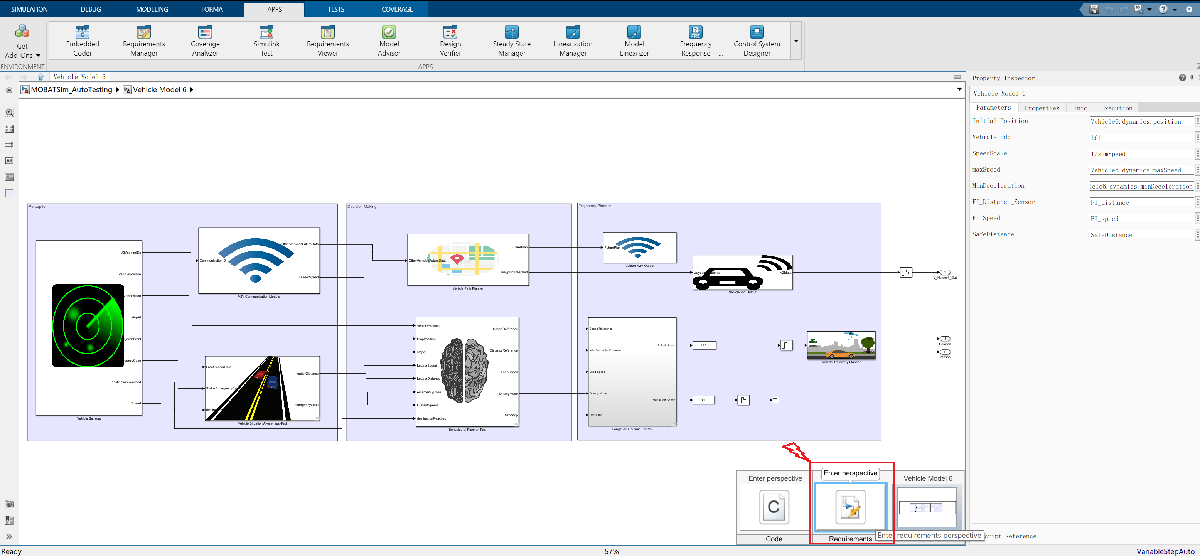

Then a new interface **Requirements Browser** will appear below the simulink model interface.

The process of creating a new requirement set and a new requirement is consistent with the steps in the Requirements Editor.

Click on the newly created requirement, you can author your requirements by writing the content, ID, summary etc. in the **Properities** tab in the **Property Inspector** pane on the right:

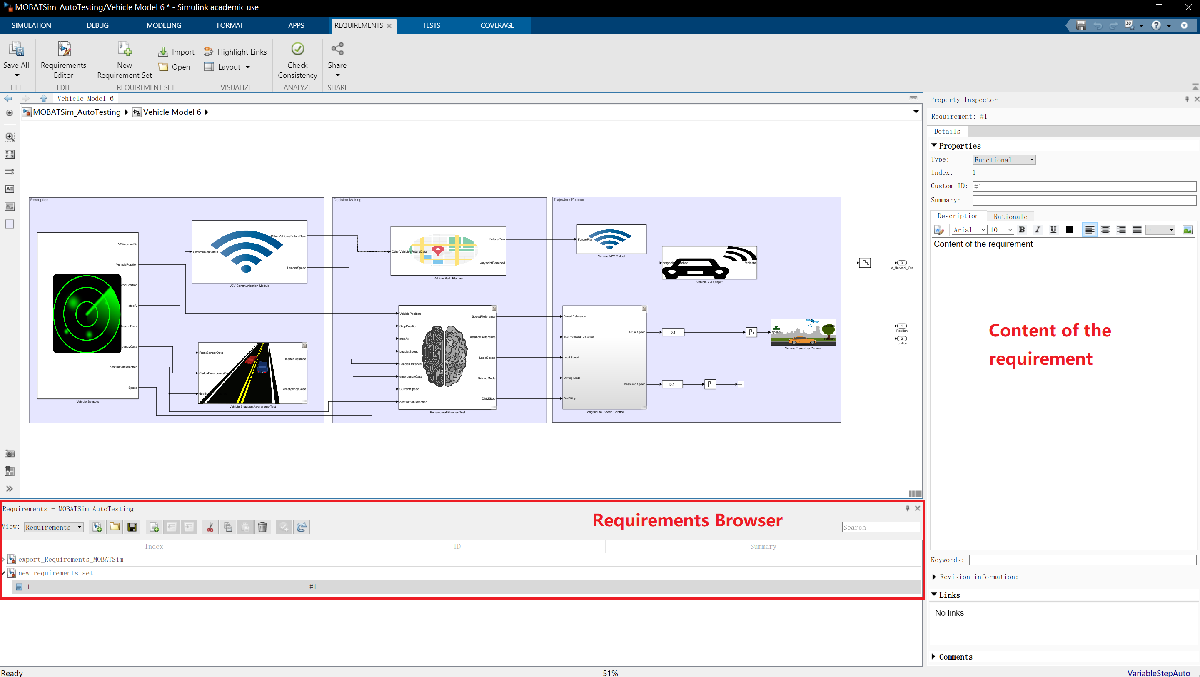

To go back to Table of Contents

## **C. Link Requirements to Blocks**

Because requirements themselves are something that cannot be understood by the machine, it is necessary to link requirements to different places to verify whether the tested blocks satisfy their corresponding requirements. 

After the requirements are established, the requirements should be linked with their corresponding block, the linked block need to satisfy these requirements. The connection is bidirectional, meaning that you can locate a requirement from a model element and a model element from a requirement.

Because you can manage your requirements through the Requirements Editor or Requirements Browser, there are also two ways to link the tested blocks with their corresponding requirements.

To go back to Table of Contents

### **1. Create Links through the Requirements Editor**

Because the connection between requirements and blocks is bidirectional, you can select the block to be linked in the model interface, and then right click on the requirements to be linked in the Requirements Editor, and click "link from "block_name" " to create the links:

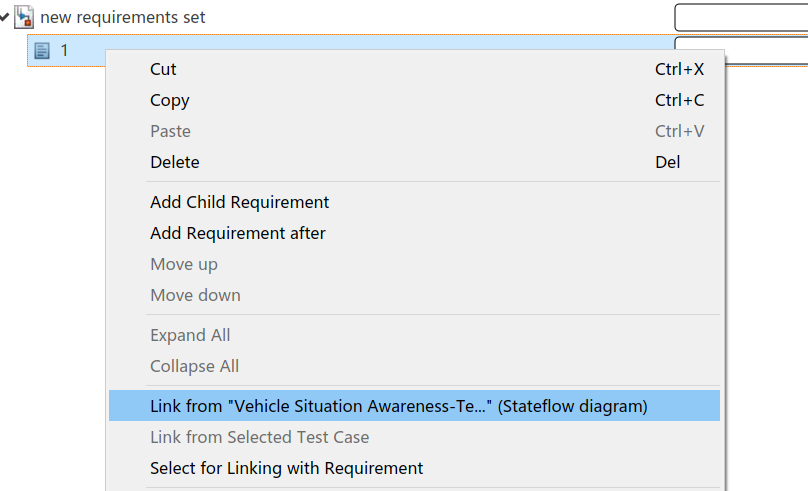

You can also first select the requirements to be linked in the Requirements Editor, then right click on the block to be linked in the model interface, select "Requirements", and then click "Link to Selection in Requirements Browser" to create the links:

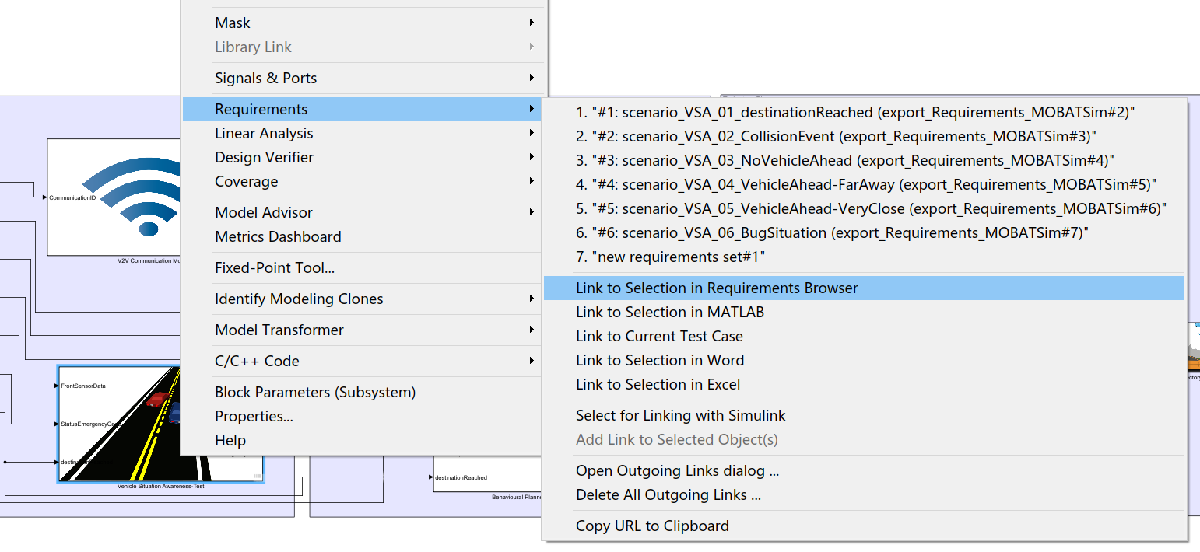

In addition to creating links by selecting blocks and requirements, you can also create links between requirements and blocks by dragging requirements from the Requirements Editor and dropping it on the corresponding block. 

To go back to Table of Contents

### **2. Create Links through the Requirements Browser**

The process of creating links through the Requirements Browser is the same as the process of creating links through the Requirements Editor.

To go back to Table of Contents

### 3. View Links between Requirements and Blocks

After creating the links, you can view these links through the linked blocks, Requirements Editor, or Requirements Browser.

After you create links between requirements and blocks, a traceability data file will be automatically generated, named "`TestModel_name.slmx`", and saved in the same path as the test model.

To go back to Table of Contents

#### View Links through the linked Blocks

When you right click on a block and select "Requirements", all the requirements linked to the block will be displayed at the top of the menu that appears.

To go back to Table of Contents

#### View Links through the Requirements Editor

In the Requirements Editor, you can view the "Implementation Status" of each requirement. When the requirement has been linked to a block, the "Implementation Status" is displayed in blue. Select a requirement, the corresponding linked block will be displayed on the **Links** tab on the right, click to jump directly to the block in Simulink:

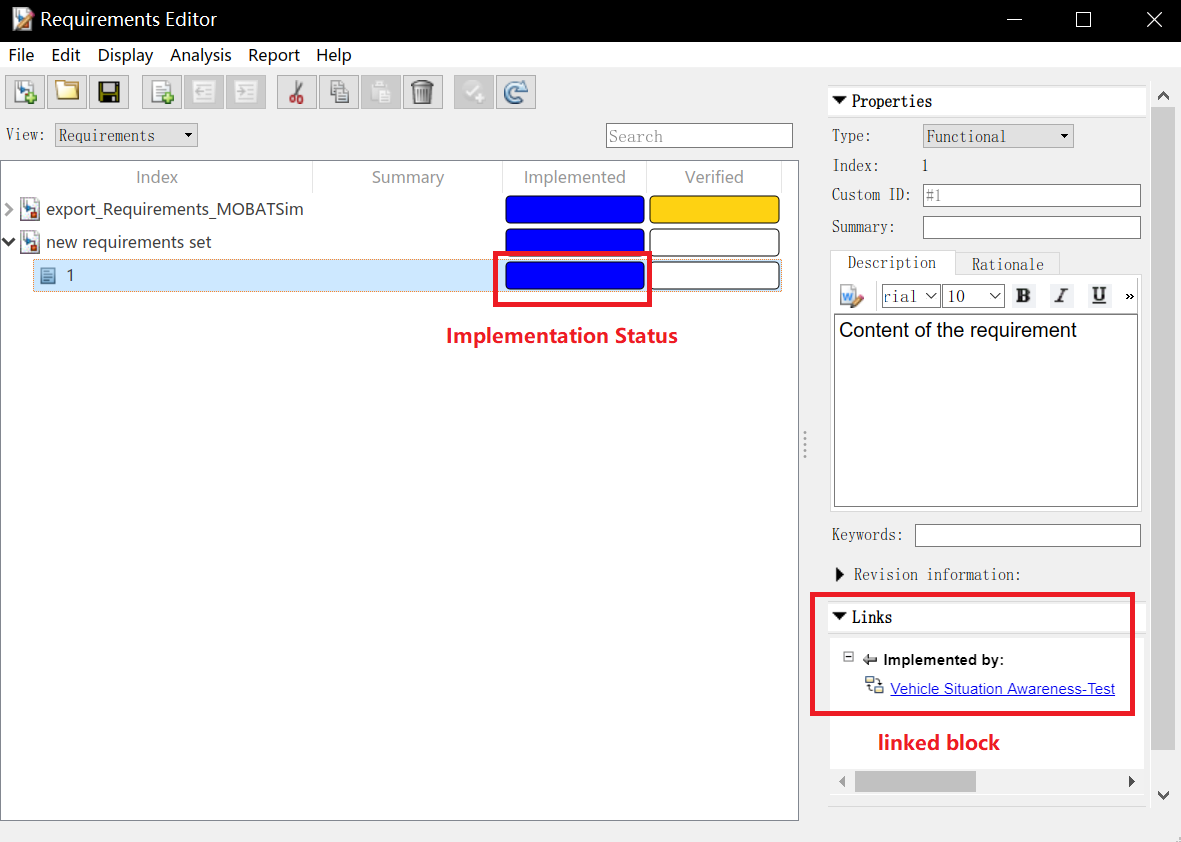

To go back to Table of Contents

#### View Links through the Requirements Browser

After you create the links, every time you enter the Requirements Perspective and open the Requirements Browser, a small badge will be displayed in the upper right corner of the blocks in the Simulink model which are linked with requirements. Clicking on the badge will display all the requirements linked to this block:

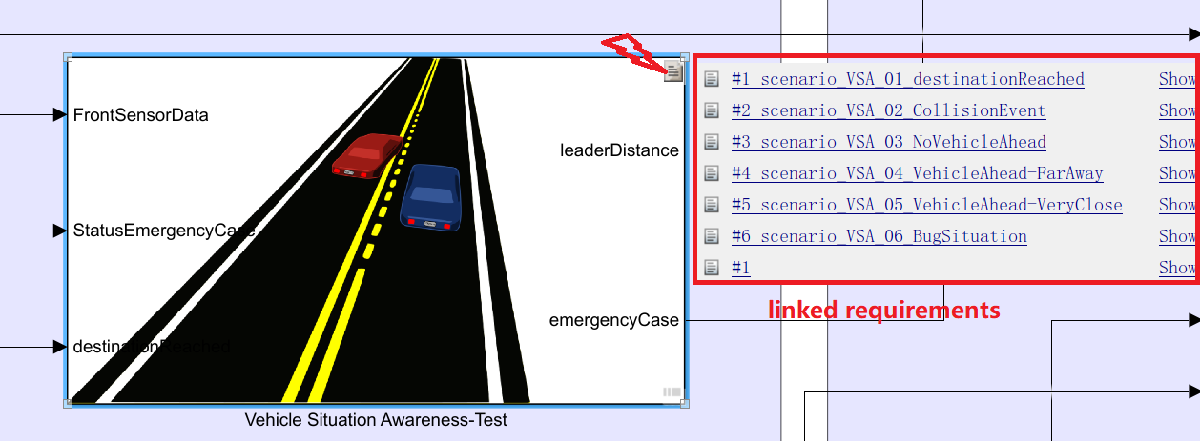

Select a requirement in the Requiremens Browser, the corresponding linked block will be displayed on the **Links** tab on the right, click to jump directly to the block in Simulink (same as in Requirements Editor).

To go back to Table of Contents

# **Ⅲ. Determine Test Signals**

Now you have defined the requirements of the blocks that need to be tested. To test these blocks, you need to check whether the existing input/output signals of the tested blocks are sufficient for testing and verifying all requirements. 

To go back to Table of Contents

## **A. Missing Signals**

If the existing input/output signals of a block are not sufficient for testing and verifying all requirements, you need to add input/output signals for the block. In MOBATSim, the blocks with missing signals are usually MATLAB system blocks, and these blocks usually hide a lot of signals. For the MATLAB system blocks to be tested, the missing input signal can be derived from the previous block.

To go back to Table of Contents

## **B. Enough signals**

If the existing signals are sufficient for testing, there is no need to modify the signals of the tested block.

To go back to Table of Contents

# **Ⅳ. Create Test Harness**

A test harness is a model that isolates the components under test, with inputs, outputs, and verification blocks configured for testing scenarios. You can create a test harness for a model component or for a full model. A test harness gives you a separate testing environment for a model or a model component. Here, you can isolate individual blocks for unit testing.

Compared to using separate models for unit testing, test harnesses offer management and synchronization capabilities in the model canvas.

For more detailed information about Test Harness, please click [here](https://www.mathworks.com/help/sltest/test-harnesses.html).

To go back to Table of Contents

## A. Start creating Test Harness

Right click on the block that needs to be tested, choose "Test Harness", and then click "Create for 'block_name' "  to open the Create Test Harness dialog box:

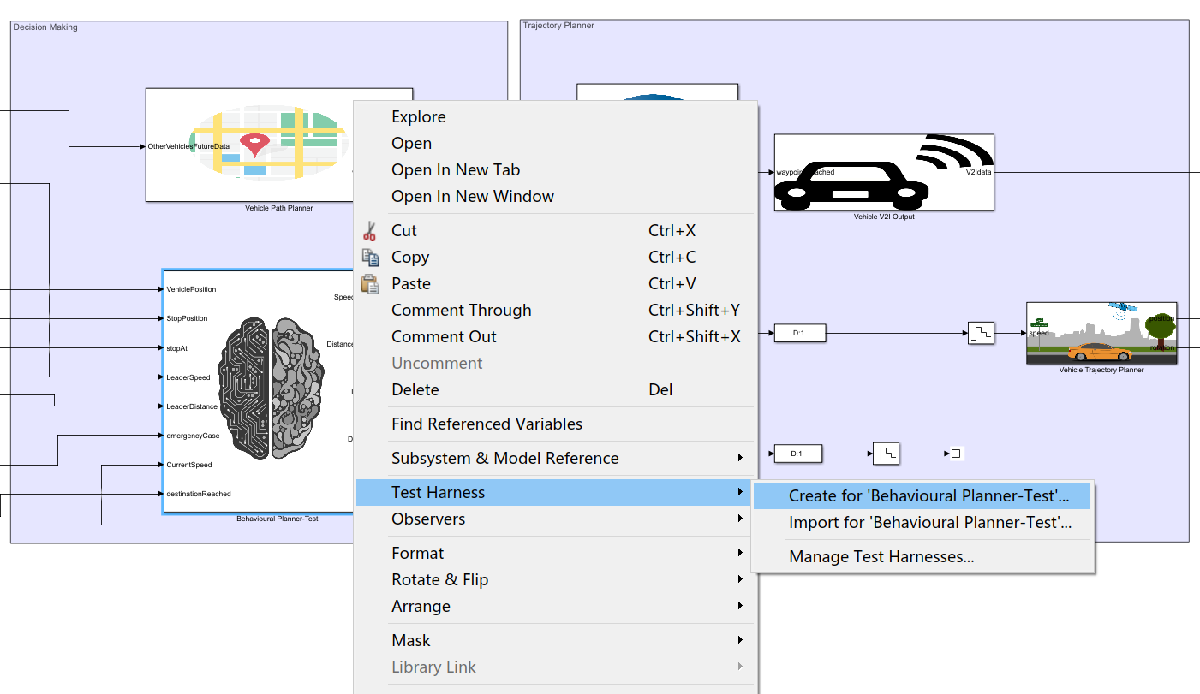

To go back to Table of Contents

## B. Specify the Properties of a Test Harness

In the Create Test Harness dialog box, you can specify different properties of the test harness. 

You can specify the name of the test harness, the Source and Sinks of the test harness, whether to create a separate test assessment block in the test harness model, etc. :

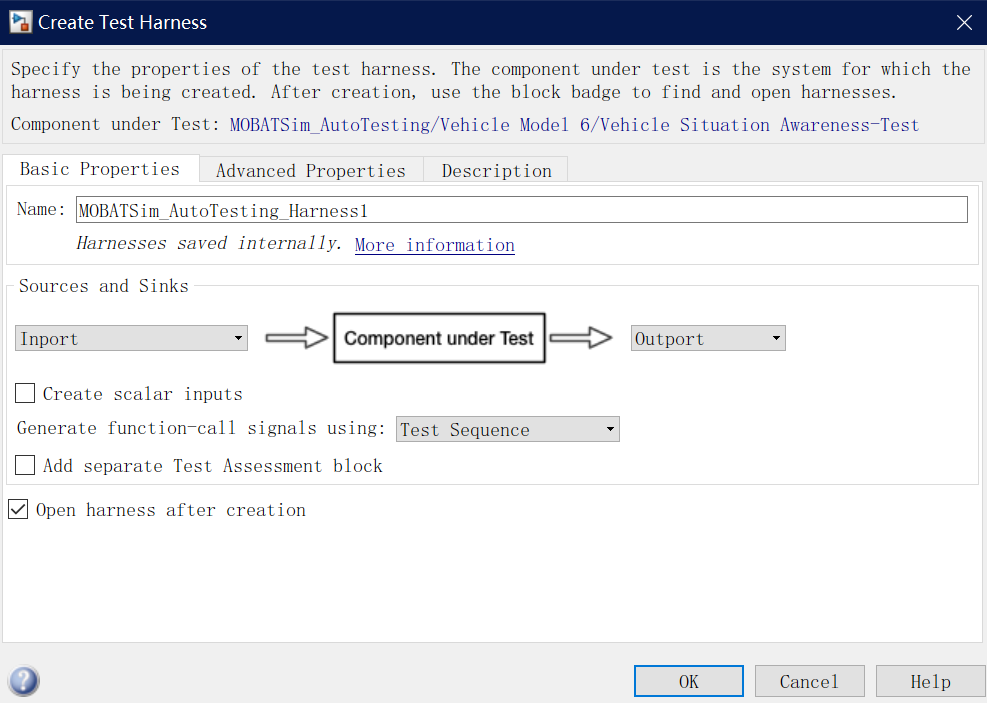

After setting the properties of the test harness, click **OK** to create a new test harness.

You can also create a new test harness directly through the following code:

sltest.harness.create('MOBATSim_AutoTesting/Vehicle Model 6/Vehicle Situation Awareness-Test', ... %specify the harness owner
    'Name','harness_name', ...        %set the name of test harness
    'Source','Signal Builder', ...    %choose Source
    'Sink','Outport', ...             %choose Sink
    'SeparateAssessment',true)        %add a seperate test assessment block

For more detailed information about properties of a test harness, please click [here](https://www.mathworks.com/help/sltest/ug/select-test-harness-properties-for-your-task.html).

To go back to Table of Contents

### 1. Sources and Sinks

Sources provide test inputs for the component under test in the test harness model, and Sinks specify the output of the test harness:

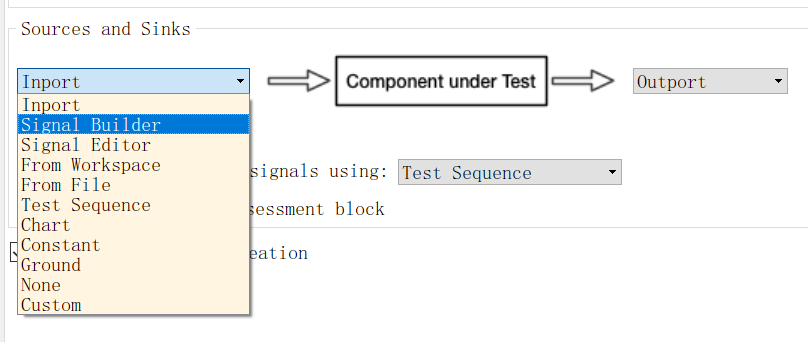

When selecting Source, if you use external data files as test inputs, choose "From File"; if you select the data in Workspace as test inputs, choose "From Workspace"; if you directly create test inputs for the component under test in the test harness model, you can choose these signal input blocks: Signal Builder, Signal Editor, Test Sequence.

In the existing test harnesses in this test model, we have chosen Signal Builder as test input generator.

When there is no need to export the test output data of the test harness, keep the default Sink unchanged, which is "Outport".

To go back to Table of Contents

#### Signal Builder

The Signal Builder block allows you to create interchangeable groups of piecewise linear signal sources and use them in a model. You can quickly switch the signal groups into and out of a model to facilitate testing.

Double-click on the block to open the editor, and all input signals are displayed in the form of charts:

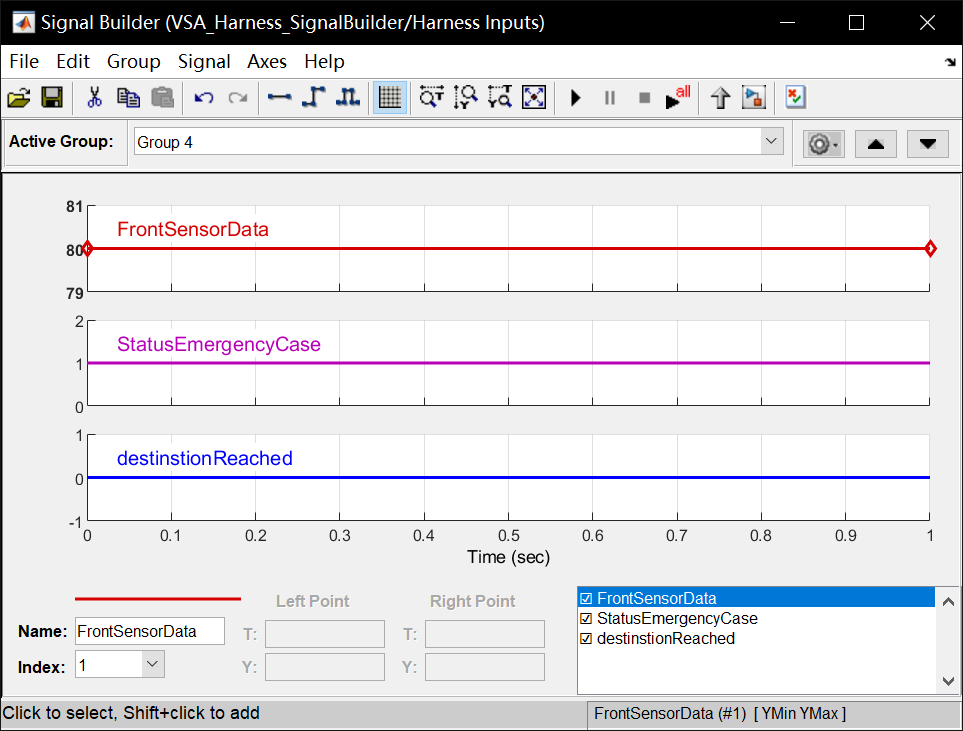

For more detailed information about Signal Builder, please click [here](https://www.mathworks.com/help/simulink/slref/signalbuilder.html).

To go back to Table of Contents

#### Signal Editor

The Signal Editor block displays, creates, and edits interchangeable scenarios. You can also use the block to switch scenarios in and out of models. 

The Signal Editor provides similar functionality to the Signal Builder block, but with greater flexibility. 

You can replace the Signal Builder with the Signal Editor block. To port signal data and properties from the Signal Builder block to Signal Editor block, use the [signalBuilderToSignalEditor](https://www.mathworks.com/help/simulink/slref/signalbuildertosignaleditor.html#mw_a9622ecc-d5ae-4842-9b47-960ba6006b8a) function.

For more detailed information about Signal Editorr, please click [here](https://www.mathworks.com/help/simulink/slref/signaleditorblock.html).

To go back to Table of Contents

#### Test Sequence

The Test Sequence block can be used to create simulation testing scenarios, function calls, and assessments. In this block, you can define a test sequence using a tabular series of steps.

A test sequence consists of test steps arranged in a hierarchy. You can use a test sequence to define test inputs and to define how a test will progress in response to the simulation. A test step contains actions that execute at the beginning of the step. A test step can contain transitions that define when the step stops executing, and which test step executes next:

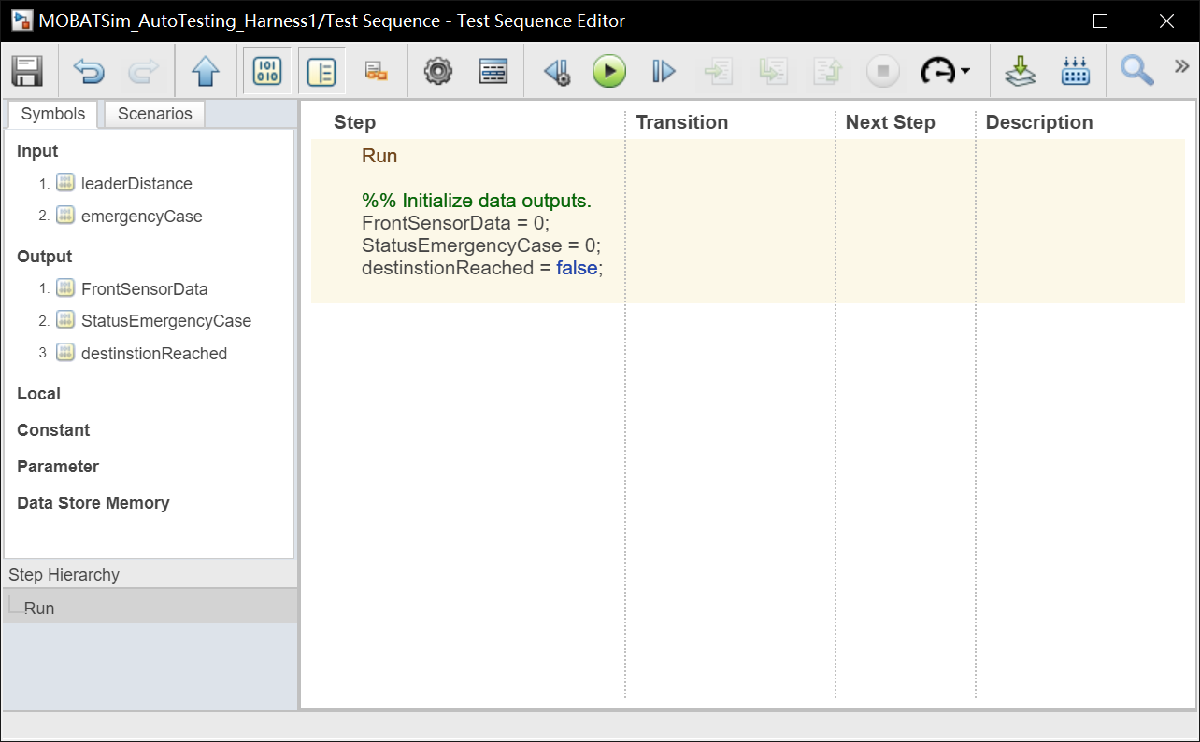

For more detailed information about Test Sequence, please click [here](https://www.mathworks.com/help/sltest/ug/introduction-to-test-sequences.html).

To go back to Table of Contents

### 2. Add seperate Test Assessment Block

In the Create Test Harness dialog box, you can select **Add separate Test Assessment block** to include a separate Test Assessment block in the test harness:

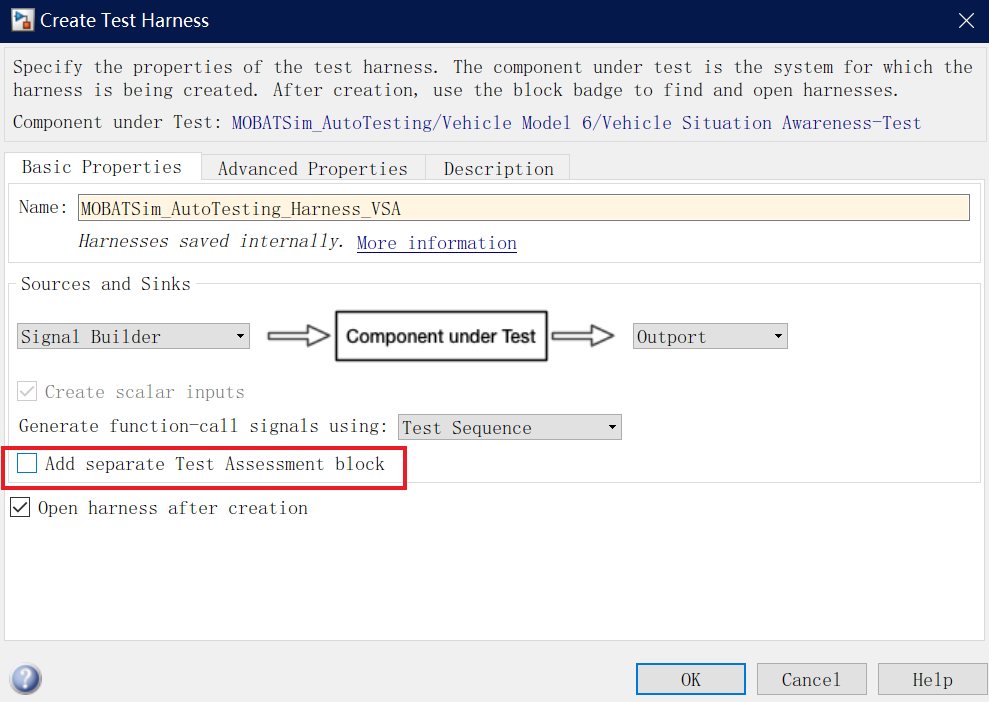

A Test Assessment block is a separate Test Sequence block configured with properties commonly used for verifying the component under test. In this block, use input and output signals to write logical or temporal requirements-based assessment criteria to verify whether the component under test meets the corresponding requirements in the test:

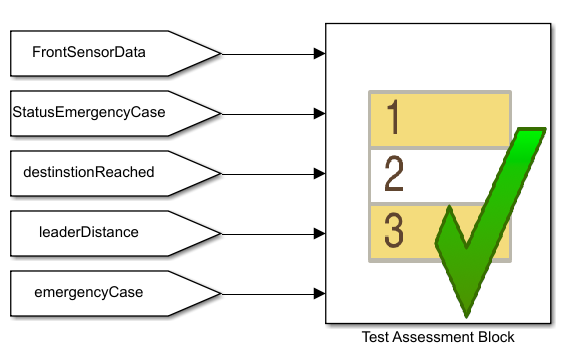

Double-click the Test Assessment block to open the Test Sequence Editor. By default, the Test Assessment block contains a test step Run, configured as a When decomposition sequence. To change the transition type to a standard transition, right-click the top-level step and clear **When decomposition**:

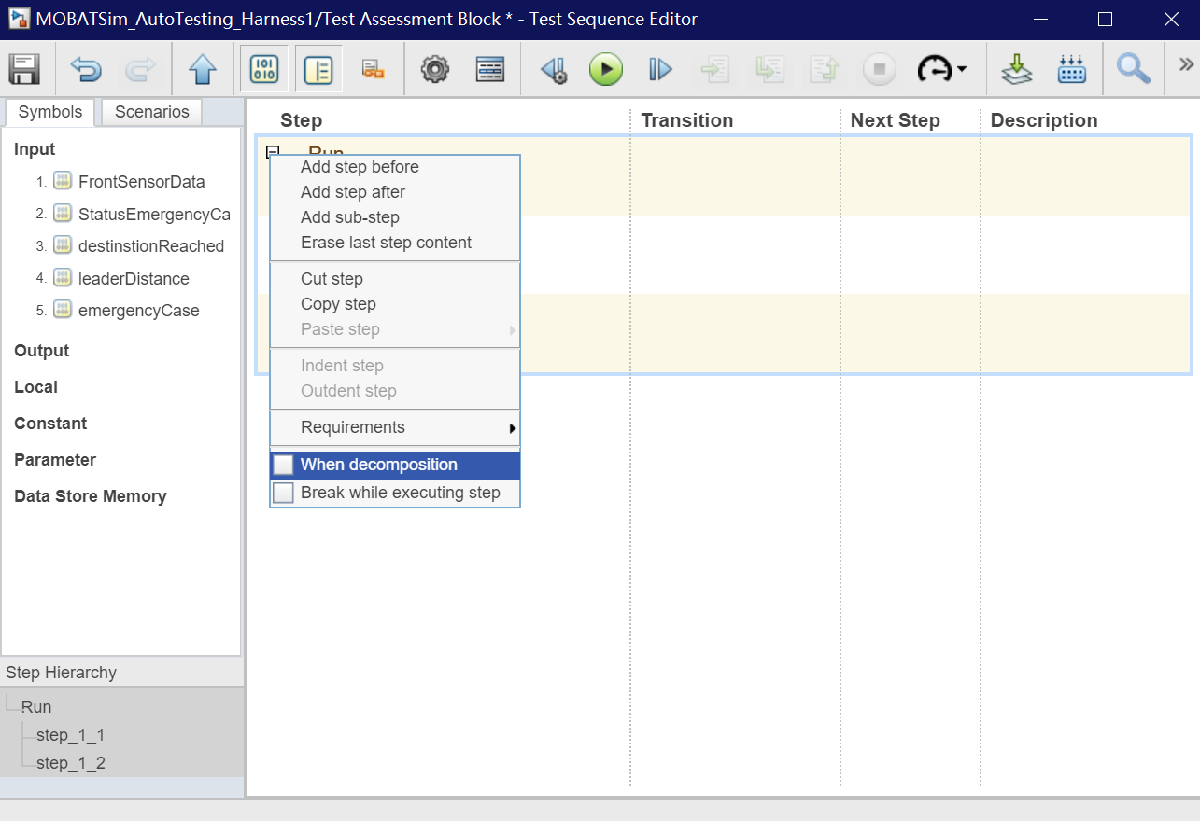

Generally we use two syntaxes to write test assessments: verify Statements and assert Statements**.**

In the existing test harnesses, we all use `verify` Statements to write test assessments that [verify multiple conditions at a time](https://ww2.mathworks.cn/help/sltest/ug/verify-multiple-conditions-at-a-time.html).

For more detailed information about Test Sequence and Assessment Syntax, please click [here](https://www.mathworks.com/help/sltest/ug/syntax-for-test-sequences-and-assessments.html).

To go back to Table of Contents

#### `Verify` Statements

A `verify` statement evaluates a logical expression and returns a pass, fail, or untested result for each simulation time step. `verify` statements can include temporal and conditional syntax. A failure does not stop simulation. 

A `fail` at any time step results in an overall `fail`. If there are no failing results, a `pass` at any time step results in an overall `pass`. Otherwise, the overall result is `untested`. Results appear in the **Verify Statements** section of the test results in the Test Manager.

For more detailed information about verfiy Statements, please click [here](https://ww2.mathworks.cn/help/sltest/ug/connecting-blocks-for-verify-statements.html).

To go back to Table of Contents

#### `Assert` Statements

You can use `assert` statements in a Test Assessment or Test Sequence block to stop executing an invalid test. `assert` evaluates a logical argument, but unlike `verify`, `assert` stops simulation. Failures stop simulation and returns simulation errors. To make results easier to interpret, add an optional message to display the simulation error message.

For more detailed information about assert Statements, please click [here](https://www.mathworks.com/help/matlab/ref/assert.html).

To go back to Table of Contents

## **C. Test Harness Model**

The created test harness models are divided into two types: the harness model with Test Assessment Block and the harness model without Test Assessment Block.

To go back to Table of Contents

### **1. Model with Test Assessment Block**

If you select Add separate Test Assessment block before, in this case, the test harness model includes a seperate Test Assessment block, a signal input block(Source), the isolated component under test, a signal output block(Sink):

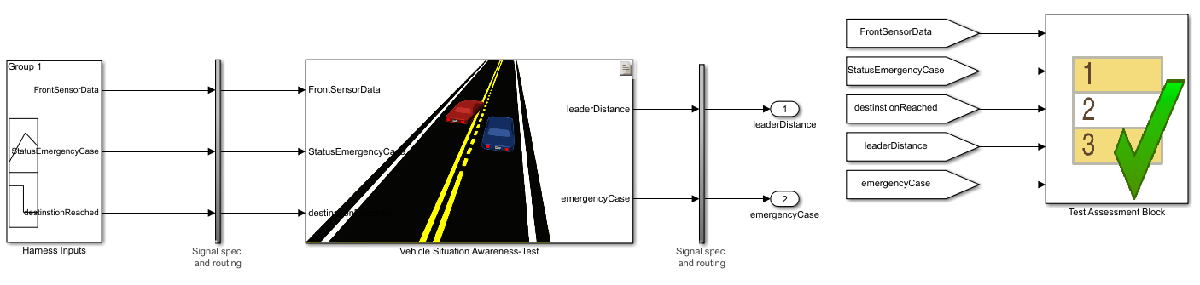

Create test inputs for the test in the signal input block on the left in the harness model. 

The commonly used input blocks are Signal Builder, Signal Editor, Test Sequence.

The assessment criteria that are used to evaluate whether the component under test meets all requirements are written in this test assessment block, that is, requirements-based assessments are integrated into In the test harness model. 

After setting the test inputs and test assessments, close the test harness.

To go back to Table of Contents

### **2. Model without Test Assessment Block**

In this case, the test harness model includes a signal input block(Source), the isolated component under test, a signal output block(Sink):

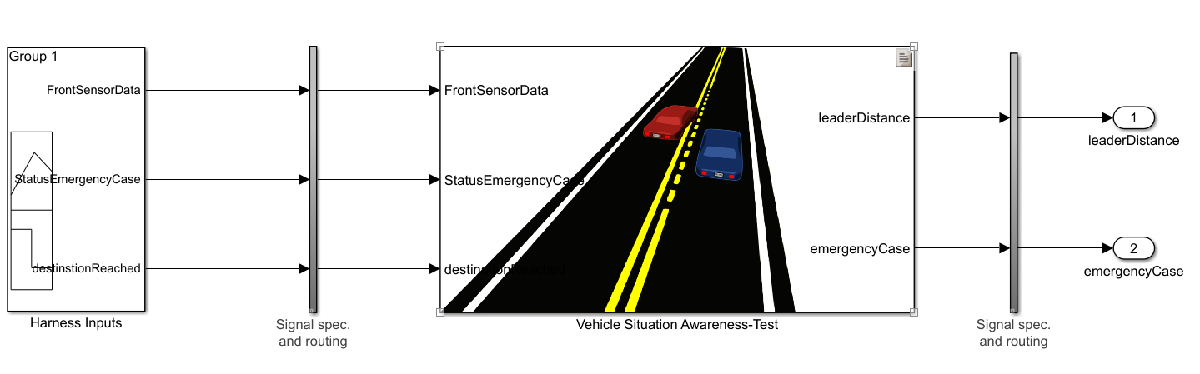

Create test inputs for the test in the signal input block on the left in the harness model. 

Since the test harness model does not include a seperate Test Assessment block, test assessments cannot be written here. **Warning**: In this case, we will define test assessments in Test Manager later!

After setting the test inputs, close the test harness.

To go back to Table of Contents

# **Ⅴ. Create Test Cases**

Create a test file in the tool Simulink Test Manager, and create test cases for testing in the test file, then specify the properties of the test cases.

To go back to Table of Contents

## A. Simulink Test Manager

To start the Test Manager, on the **Apps** tab, under** Model Verification, Validation, and Test**, click **Simulink Test**. On the **Tests** tab, click **Simulink Test Manager**.

You can also directly run the following code to open the Test Manager:

% Open Test Manager to view and edit test case
sltest.testmanager.view;

The Test Manager mainly consists of two parts: Test Browser, Results and Artifacts. Test Browser is used to manage test files and test cases in the Test Manager, and set test options. Results and Artifacts are used to view and evaluate test results:

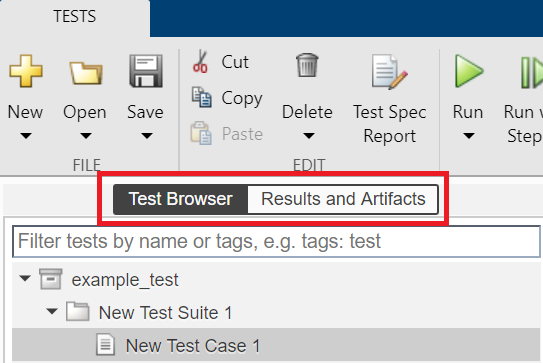

To go back to Table of Contents

## B. Create Test Cases

Click **New** in the upper left corner of the Test Manager toolstrip, then choose **Test File **to create a new blank test file. When a new test file is created, a test suite and a test case will be automatically created in the test file by default. 

Each test case can be assigned a different running mode. The test case created by default runs baseline test. In our case, simulation test is used for testing. 

Right-click on the test case generated by default, choose "**Convert to**", and then click "**Simulation Test**".

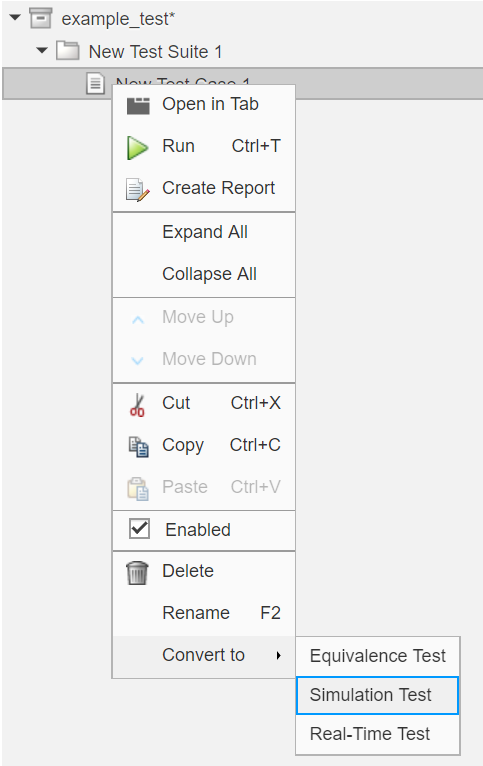

You can also directly run the following code to create a new test file and test case in it:

% Create the test file, test suite, and test case structure
tf = sltest.testmanager.TestFile('TestFile_name');   %create a new test file
ts = createTestSuite(tf,'TestSuite_name');    %create a new test suite
tc = createTestCase(ts,'simulation','TestCase_name');   %create a new test case with simulation mode
%'simulation/equivalence/baseline' specifies different running mode for the test case

To go back to Table of Contents

## C. Specify the Properties of Test Cases

After you create the test cases, you need to make some settings for the test file and each test case.

First of all, you must know that the test file is at the top of the hierarchy. According to your settings, it will contain several test suites of different levels. The test suites at the lowest level contain several test cases. Then the settings for test suites are valid for all the test cases under it. The last is the test case's own settings.

When certain settings apply to all test cases, you should directly modify the corresponding properties in the test file.

The main settings we perform are: set the Coverage Settings for the test file; for each test case, set its Requirements, System under Test, Inputs, and when necessary, set its Logical and Temporal Assessments for some test cases.

To go back to Table of Contents

### 1. Coverage Settings

The settings here apply to all test cases, so modify the settings of the test file directly.

Click the test file, the properties of the test file will be displayed on the right side of the Test Browser. Expand the tab "**COVERAGE SETTINGS**" to select the test coverage settings:

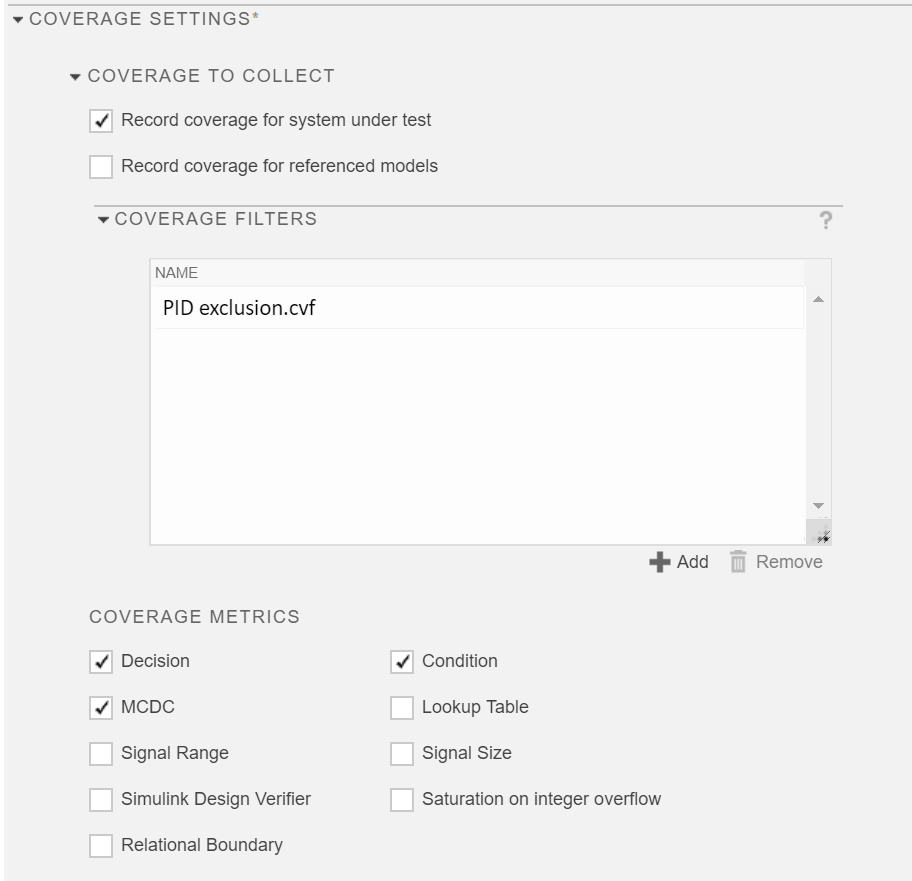

To go back to Table of Contents

#### Coverage to Collect

Check "**Record coverage for system under test**" under the tab **COVERAGE TO COLLECT**.

To go back to Table of Contents

#### Coverage Filters

A file with the suffix "`.cvf`" can be added under the tab **COVERAGE FILTERS** to exclude certain components from coverage analysis, and the coverage information of these components is not collected during the test. Because not all components can be analyzed by various coverage metrics.

Here, we need to exclude the component `PID controller` in the Simulink library from coverage analysis, so we created a file called "`PID exclusion.cvf`" and added it here:

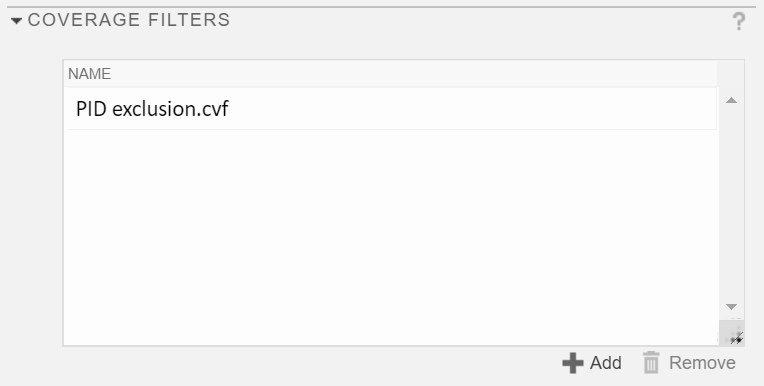

If you have other components that you do not want or cannot collect coverage information during the test, you need to [create and use Coverage Filters](https://www.mathworks.com/help/slcoverage/ug/creating-and-using-coverage-filters.html), to create the same file and add it here. 

For more detailed information about which components can receive which coverage, please click [here](https://www.mathworks.com/help/slcoverage/ug/model-objects-that-receive-coverage.html).

To go back to Table of Contents

#### Coverage Metrics

Under the tab** COVERAGE METRICS**, you can select the type of coverage you want to collect in the test, and different coverage metrics analyze different coverage information. Usually we choose **Decision**(Decision Coverage), **Condition**(Condition Coverage), **MCDC**(Modified Condition/Decision Coverage).

For more detailed information about Model Coverage, please click [here](https://www.mathworks.com/help/slcoverage/ug/types-of-model-coverage.html).

To go back to Table of Contents

### 2. Requirements

Click on a test case, expand the tab **Requirements** on the right side of the interface, here link the test case and the requirements verified by the test case.

The links between test cases and requirements here are the same as the previous links between blocks and requirements, which are bidirectional. 

You can create a link by selecting the corresponding requirements in the Requirements Editor or Requirements Browser, and then clicking **Add** under the tab **Requirements** of the test case, and then clicking "**Link to Scelected Requirement**":

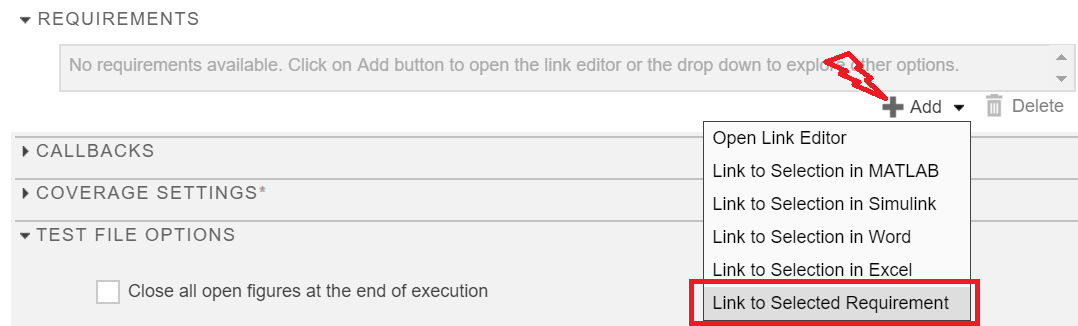

You can also select the test case to be linked in the Test Manager first, then right-click the requirements to be linked in the Requirements Editor or Requirements Browser, and select "**Link from Selected Test Case**" to create a link:

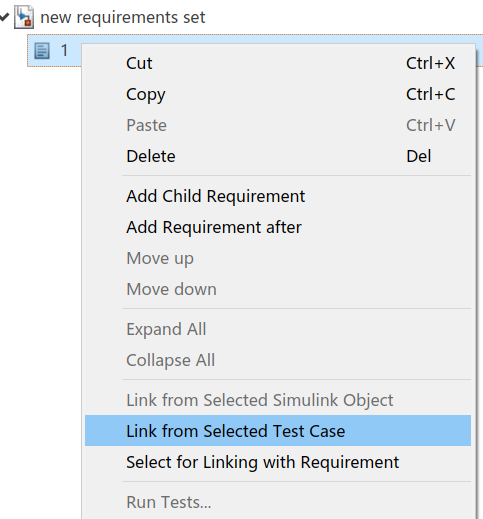

To go back to Table of Contents

### 3. System under Test

Expand the tab **SYSTEM UNDER TEST**, specify the model you want to test. Click **Use current model **button to automatically choose the currently activated model for the test case.

Then select the corresponding test harness under the tab **TEST HARNESS** to use for the test case.

Under the tab **SIMULATION SETTINGS AND RELEASE OVERRIDES**，set the **Simulation Mode** to **Normal**: 

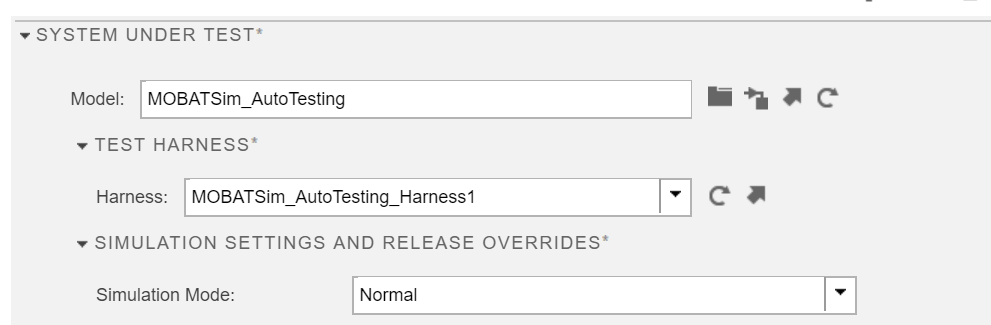

To go back to Table of Contents

### 4. Inputs

Here, you can choose whether to use external files as the test inputs of the test cases. If you use different signal groups in the signal input block of the test harness model to define different test scenarios, then you need to specify the signal group for testing for the test case:

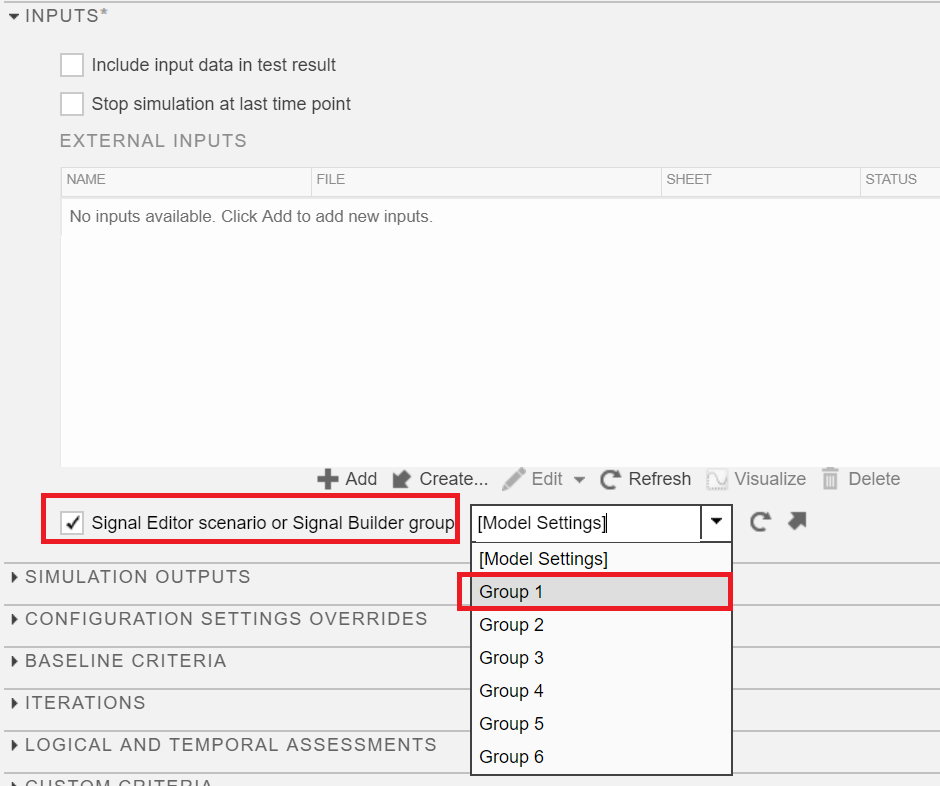

To go back to Table of Contents

### 5. Logical and Temporal Assessments

If you have previously added Test Assessment blocks to all test harness models, you can skip this step. You don't need to author assessments for test cases anymore.

If you **did not** select add seperate Test Assessment block for some test harness when you created the test harness model earlier, then you need to add assessments here for the test cases executed by those test harnesses that do not include a Test Assessment block.

For more detailed information about how to author the logical and temporal assessments here, please click [here](https://www.mathworks.com/help/sltest/ug/temporal-assessment-parameters.html).

To go back to Table of Contents

## D. View Links between Test Cases and Requirements

Just like the previous View Links between Requirements and Blocks, you can view these links through the linked test cases, Requirements Editor, Requirements Browser.

After you create links between test cases and requirements, a traceability data file will be automatically generated, named "`TestFile_name.slmx`", and saved in the same path as the test file.

To go back to Table of Contents

### 1. View Links through the linked Test Cases

After creating the link between the test case and the requirement, click on the test case, you can see the requirement of the link in the tab Requirements, and click to jump directly to the corresponding requirement in the Requirements Editor.

To go back to Table of Contents

### 2. View Links through the Requirements Editor

After creating the link between the test case and the requirement, click on the requirement, and you can see that its **Verification Status** is displayed in yellow, which means that the requirement is linked to at least one test case, but the linked test case has not been run. Under the tab **Links** on the right, the linked test case will be displayed. Click to jump directly to the corresponding test case in the Test Manager:

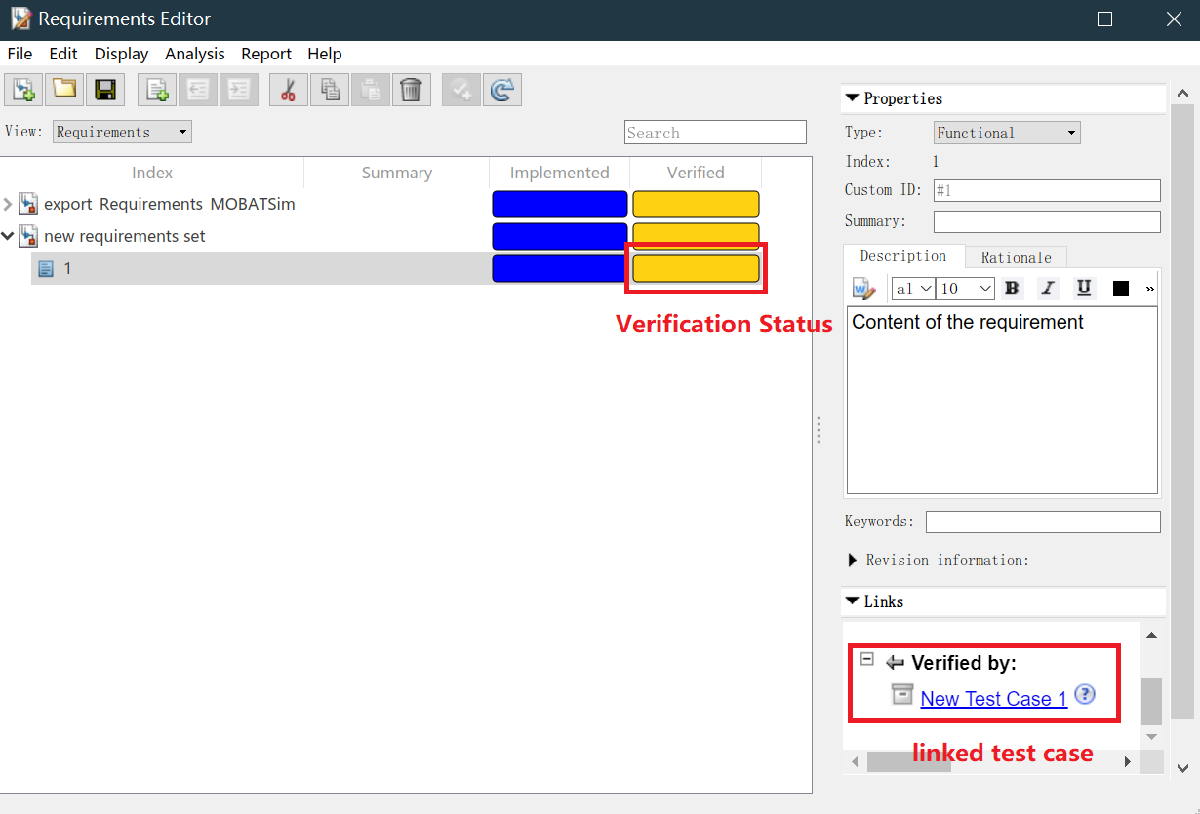

To go back to Table of Contents

### 3. View Links through the Requirements Browser

In the Requirements Browser, you cannot view the Verification Status. Click the linked requirement, and the linked test case will be displayed under the tab** Links** on the right (the same as in the Requirements Editor).

To go back to Table of Contents

# **Ⅵ. Run Test Cases and view Test Results**

After you set the attributes of all test cases, you can run specified test cases, or test suites, or the entire test file to execute the test. After running these test cases, you can click **Results and Artifacts** to view the test results.

To go back to Table of Contents

## A. Run Test Cases

Select the specified test cases, or test suites, or the entire test file, and click **Run** in the toolstrip to run these test cases to execute the test.

To go back to Table of Contents

## B. View Test Results

After a test case has finished running in the Test Manager, the test case result becomes available in the **Results and Artifacts** pane. Test results are organized in the same hierarchy as the test file, test suite, and test cases that were run from the **Test Browser** pane. In addition, the **Results and Artifacts** pane shows the criteria results and simulation output, if applicable to the test case.

Below I will introduce the test results after testing a certain block in our test model. When we open the test result on the left, click on the top level of the test result, and the following five parts information are displayed:

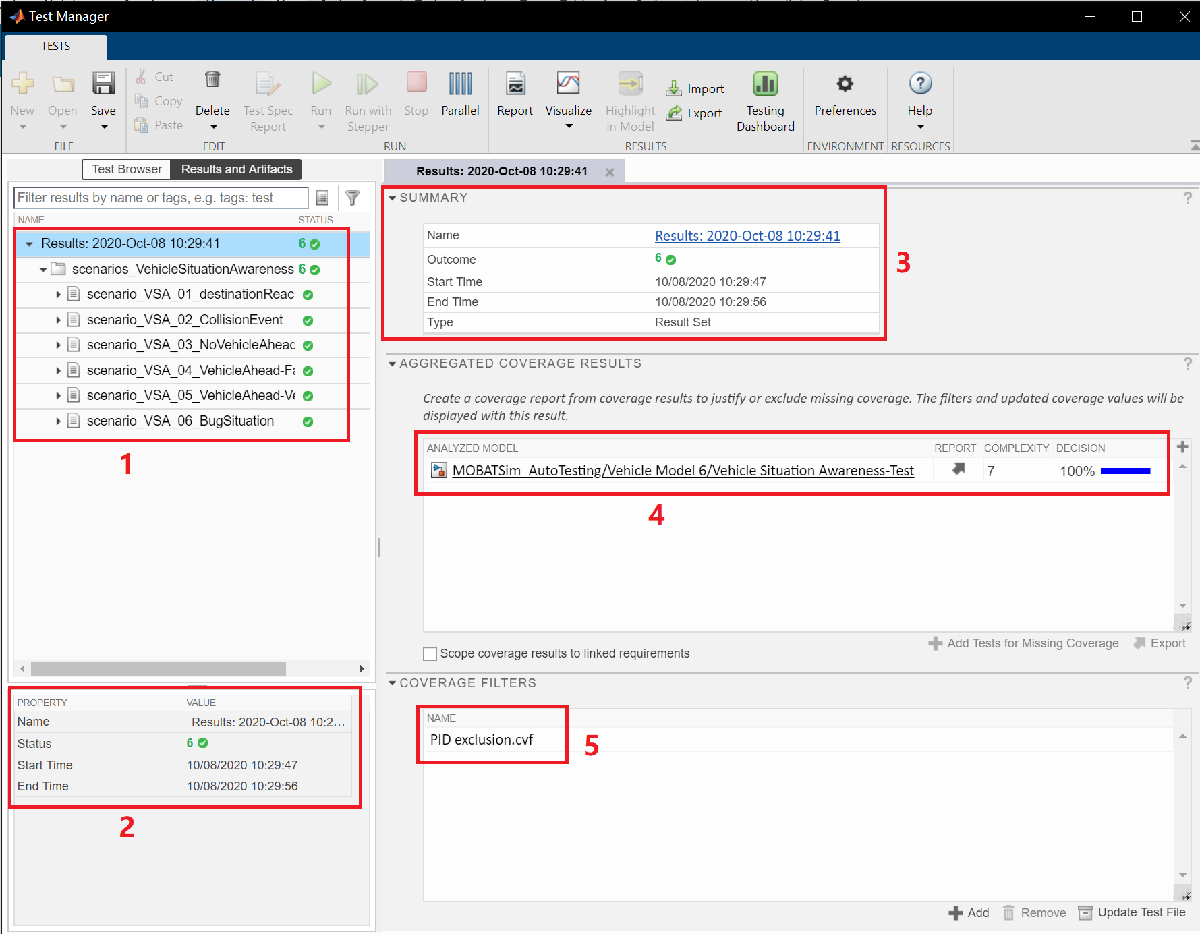

- Test results of the test suite and each test case, the green icon indicates that the test case passed the test;

- Information about the test, such as the test time, and the status of the test result;

- The summary information of the test, when at the top level of the test result, the content is the same as part 2;

- Test coverage result of the tested block in the selected coverage metrics;

- Coverage Filter information.

We have selected three coverages in Coverage Metrics, but only the results of Decision Coverage are shown here, because the tested block only contains parts that can be analyzed by Decision Coveage.

Double-click a test case result,  and select **Expand All Under** to see all the detailed test results of this test case:

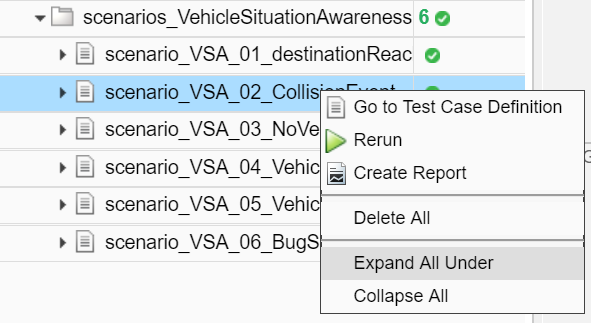

The detailed test results of this test case are divided into two parts:** Verify Statements** and **Sim Output**.

Under the section of** Verify Statements**, you can see the status of different assessments. The green mark indicates that the assessment was triggered when the test case was run, and the test case passed the assessment; The prohibition mark indicates that the assessment has not been triggered during the running of the test case:

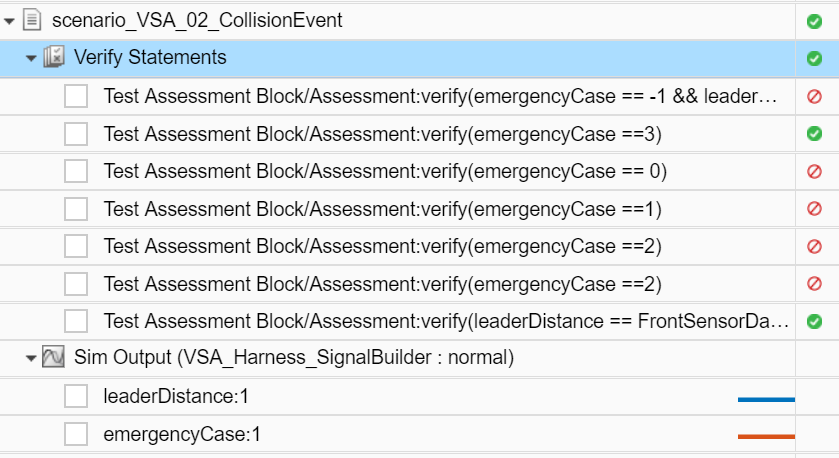

Under the section of **Sim Output**. you can see the simulation outputs of the tested block under this test case after the test.  

To go back to Table of Contents

## C. Generate a Test Report

After running the test cases, you can generate a test result report by clicking the** Report** icon in the toolstrip.

To go back to Table of Contents

## D. View the Status of the Requirement after the Test

After running the test cases, open the Requirements Editor to view the status of the requirements. You can see that the **Verification Status** of the requirements linked to the test cases that have passed the test has changed from yellow to green, which means that the related requirements have been verified in the test, that is, the tested block satisfies these requirements:

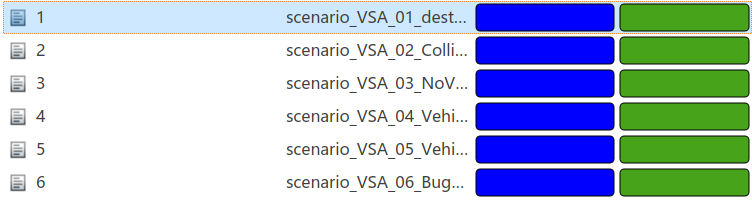

If a test case linked to a requirement fails the test, the **Verification Satus** of the requirement will be displayed in red.

To go back to Table of Contents

# **Ⅶ. Automated Testing**

After all the preparatory work is over, we have written an automatic test script named "`run_tests.m`". You can run this script to execute automated testing and generate test reports.

You can run the test script directly using the following code:

cd(CurrentPath+'\src\Misc\ModelBasedTesting')
run_tests

The automatically generated test report will also be placed in this path.

To go back to Table of Contents